1.

help pdf

 pdf Density function for a specified distribution.
    Y = pdf(NAME,X,A) returns an array of values of the probability density
    function for the one-parameter probability distribution specified by NAME
    with parameter values A, evaluated at the values in X.
 
    Y = pdf(NAME,X,A,B) or Y = pdf(NAME,X,A,B,C) returns values of the
    probability density function for a two- or three-parameter probability
    distribution with parameter values A, B (and C).
 
    The size of Y is the common size of the input arguments.  A scalar input
    functions as a constant matrix of the same size as the other inputs.  Each
    element of Y contains the probability density evaluated at the
    corresponding elements of the inputs.
 
    NAME can be:
 
       'beta'  or 'Beta',
       'bino'  or 'Binomial',
       'burr'  or 'Burr',
       'chi2'  or 'Chisquare',
       'exp'   or 'Exponential',
       'ev'    or 'Extreme Value


rand(1, 10)

ans =     0.5386    0.6952    0.4991    0.5358    0.4452    0.1239    0.4904    0.8530    0.8739    0.2703


randn(1, 10)

ans =    -1.6273    0.1663    0.3763   -0.2270   -1.1489    2.0243   -2.3595   -0.5100   -1.3216   -0.6361


2.

binopdf([0.1, 0.2, 0.3],3,0.5)

ans =      0     0     0


% Generate a sample of N variables
N = 10

N = 10

p=0.5

p = 0.5000

X = zeros(1,N)

X =      0     0     0     0     0     0     0     0     0     0


for i=1:N
    X(i)=(rand<p);
end
X

X =      0     0     1     0     0     0     1     0     0     0


X = (rand(1,N) < p)

X = 1×10 logical array
   1   1   1   0   1   1   0   0   1   0


Binomial

n = 10

n = 10

p = 0.6

p = 0.6000

U = rand(n, 1)

U =     0.1536
    0.9535
    0.5409
    0.6797
    0.0366
    0.8092
    0.7486
    0.1202
    0.5250
    0.3258


X = sum(U < p)

X = 6

X = zeros(1,N);
for i=1:N
    X(i) = sum(rand(n,1)<p);
end
X

X =      7     5     4     4     6     7     4     7     5     6


X = sum(rand(n,N)<p)

X =      3     6     6     5     5     7     8     6     4     4


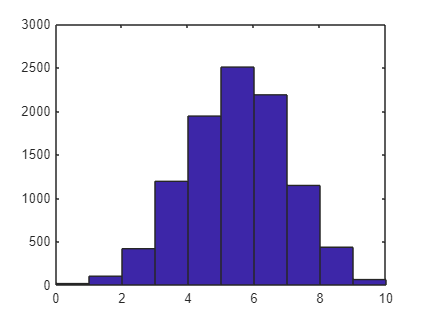

N=10000;
n=10;
X = sum(rand(n,N)<p);
hist(X)

mean(X==2) % simulated probab. P(X=2)

ans = 0.0101

binopdf(2,n,p) % true propab. P(X=2)

ans = 0.0106

abs(binopdf(2,n,p)-mean(X==2)) % error

ans = 5.1683e-04

mean(X<=2) % simulater probab P(X<=2)

ans = 0.0118

binocdf(2,n,p) % true probab P(X<=2)

ans = 0.0123

abs(binocdf(2,n,p)-mean(X<=2)) % error

ans = 4.9455e-04

mean(X<2) 

ans = 0.0017

binopdf(1,n,p) 

ans = 0.0016



mean(X) % simulated mean

ans = 5.9957

n*p % true mean

ans = 6

abs(n*p-mean(X)) %error

ans = 0.0043

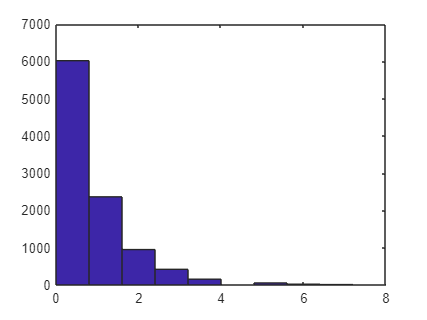

N = 10000;
X = zeros(1,N);
for i=1:N
    while rand>=p
        X(i) = X(i)+1;
    end
end
hist(X)

% poisson
lambda = 1.2;
L = lambda;
i=0;
F=exp(-L);
U = rand;
while(U>=F)
    i=i+1; F=F+exp(-L)*L^i/factorial(i);
end
X=i;
X

X = 0

N=10000;
lambda = 5;
L = lambda;
i=zeros(1,N);
F=zeros(1,N);
for j=1:N
    i=0;
    F(j)=exp(-L);
    U = rand;
    while(U>=F(j))
        i=i+1; F(j)=F(j)+exp(-L)*L^i/factorial(i);
    end
    X(j)=i;
end

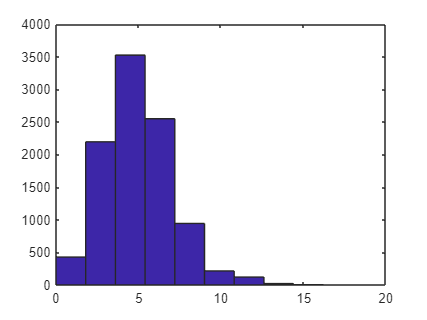

hist(X)